# Mini Project - DMX4411 - SIGNAL PROCESSING

Signal noise refers to unwanted or random electrical disturbances that interfere with the accuracy and reliability of signals in a communication system. It manifests as additional electrical fluctuations or variations superimposed on the intended signal, making it challenging to accurately interpret the original information.

The chosen signal, with a sample rate of 44,100 samples per second and a duration of 2 seconds, presents a canvas for exploration into both periodicity and the spectral composition of the audio.

close all; clear; clc;

## 1.Plot the time domain graph of the signal.

In the initial phase of our analysis, the time domain graph of the signal reveals key characteristics. The signal is sampled at a rate of 44,100 Hz and possesses a temporal extent of 2 seconds. A discernible click sound manifests in the middle of the signal. Additionally, visual inspection reveals instances of signal clipping, indicative of sound intensity surpassing the dynamic range of the recording medium.

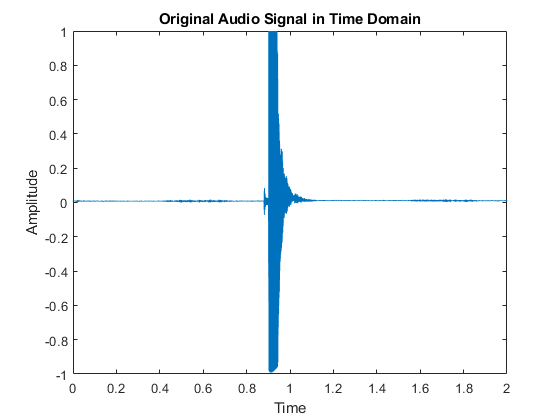

[data, sample_rate] = audioread('input/Sample 01.wav');

time = linspace(0, length(data)/sample_rate, length(data));
figure; 
plot(time, data);
xlabel("Time"); ylabel("Amplitude");
title("Original Audio Signal in Time Domain");

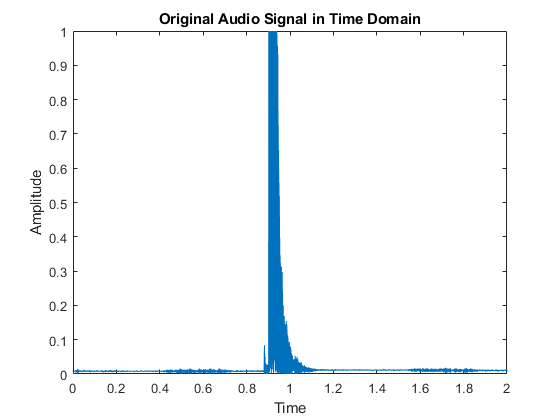

figure; 
plot(time, abs(data));
xlabel("Time"); ylabel("Amplitude");
title("Original Audio Signal in Time Domain");

## Plot the frequency spectrum (use FFT-Fast Fourier Transformation) of the signal.

By employing the Fast Fourier Transformation (FFT), the frequency spectrum of the signal was unveiled. Noteworthy features include several prominent spikes within the frequency domain graph. 

Analysis of the spectrum enables the identification of the fundamental frequency, denoted by the peak amplitude. In this instance, the highest amplitude is localized at approximately 6353 Hz, indicating the dominant frequency component. Additionally, a consistent amplitude at 0 Hz signifies a constant signal, reflecting a lack of variation and, consequently, no discernible sound. A third peak is discernible at 19060 Hz, a frequency likely beyond the audible range for humans, suggesting potential high-frequency components or harmonics.

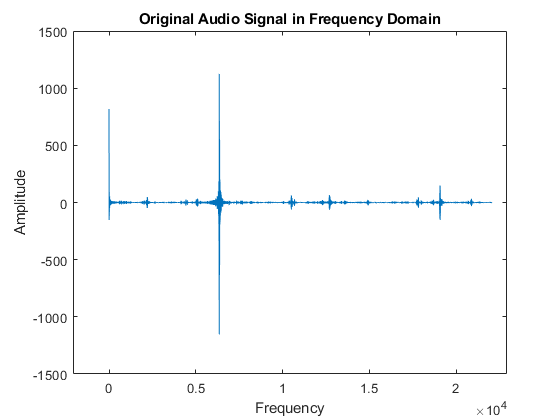

N = length(data);
frequencies = linspace(0, sample_rate, N);
spectrum  = fft(data, N);
figure; plot(frequencies(1:N/2), real(spectrum(1:N/2)));
xlabel("Frequency"); ylabel("Amplitude");
title("Original Audio Signal in Frequency Domain");

xlim([-2074 22926])

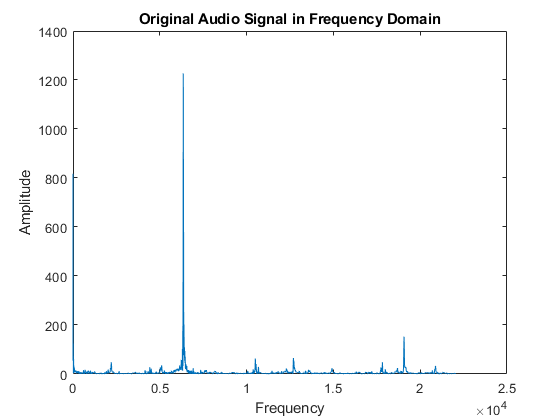

N = length(data);
frequencies = linspace(0, sample_rate, N);
spectrum  = fft(data, N);
figure; plot(frequencies(1:N/2), abs(spectrum(1:N/2)));
xlabel("Frequency"); ylabel("Amplitude");
title("Original Audio Signal in Frequency Domain");

## Identify the fundamental frequency of the signal.

This peak amplitude at around 6353 Hz signifies the fundamental frequency, representing the primary and most pronounced frequency component within the signal. 

[~, indexOfMaxValue] = max(spectrum);
fundamental_frequency = frequencies(indexOfMaxValue);
disp(['Fundamental Frequency: ', num2str(fundamental_frequency), ' Hz']);

Fundamental Frequency: 6353.072 Hz


## ## Noise Can

Implementing diverse noise elimination techniques, including Low-pass Butterworth Filter, High-pass Butterworth Filter, a custom low amplitude frequency filter, and Mean Thresholding, we successfully attenuated the undesired components within the signal. Post-denoising, the frequency domain graph was recalculated, revealing a refined and cleaner representation of the signal spectrum.

## 1. Low-pass Butterworth Filter.

Employing a Low-pass Butterworth Filter involves selectively allowing frequencies below a specified cutoff to pass through while attenuating higher frequencies. This technique is particularly effective in eliminating high-frequency noise components that may be present in the signal.


% Design and apply a low-pass Butterworth filter
cutoff_frequency = 10000; % Adjust this value based on your signal characteristics
order = 4; % Order of the Butterworth filter

% Design the filter
[b, a] = butter(order, cutoff_frequency/(sample_rate/2), 'low');

% Apply the filter to the signal
filtered_data = filter(b, a, data);

audiowrite('export/filtered_data_low.wav', filtered_data, sample_rate);

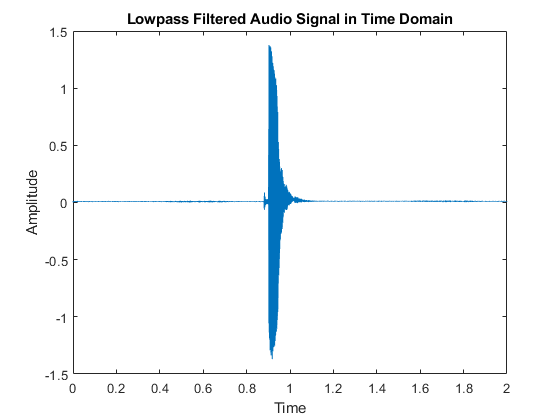

% Plot the filtered signal in the time domain
figure;
plot(time, filtered_data);
xlabel("Time"); ylabel("Amplitude");
title("Lowpass Filtered Audio Signal in Time Domain");

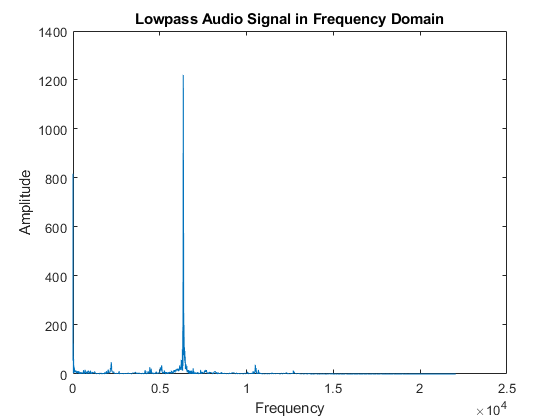

% Plot the filtered signal in the frequency domain
filtered_spectrum = fft(filtered_data, N);
figure; 
plot(frequencies(1:N/2), abs(filtered_spectrum(1:N/2)));
xlabel("Frequency"); ylabel("Amplitude");
title("Lowpass Audio Signal in Frequency Domain");

## 2. High-pass Butterworth Filter

In contrast, the High-pass Butterworth Filter allows higher frequencies to pass through while suppressing lower frequencies. This technique proves useful in mitigating low-frequency noise, enhancing the clarity of the signal by removing unwanted low-frequency components.

% Design and apply a high-pass Butterworth filter
cutoff_frequency_high = 2000; % Adjust this value based on your signal characteristics
order_high = 4; % Order of the Butterworth filter

% Design the high-pass filter
[b_high, a_high] = butter(order_high, cutoff_frequency_high/(sample_rate/2), 'high');

% Apply the high-pass filter to the signal
filtered_data_high = filter(b_high, a_high, data);

audiowrite('export/filtered_data_high.wav', filtered_data_high, sample_rate);

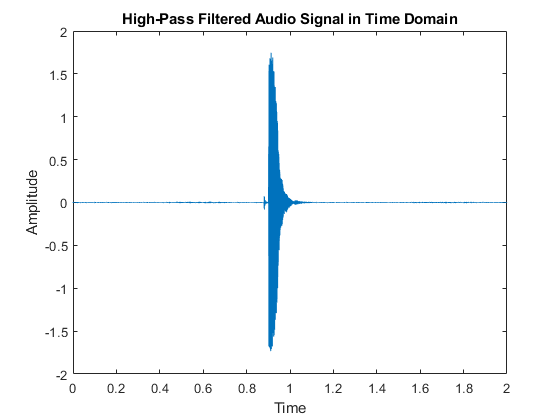


% Plot the filtered signal in the time domain
figure;
plot(time, filtered_data_high);
xlabel("Time"); ylabel("Amplitude");
title("High-Pass Filtered Audio Signal in Time Domain");

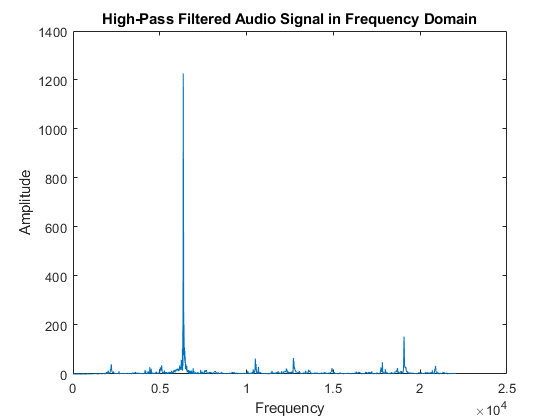

% Plot the filtered signal in the frequency domain
filtered_spectrum_high = fft(filtered_data_high, N);
figure; 
plot(frequencies(1:N/2), abs(filtered_spectrum_high(1:N/2)));
xlabel("Frequency"); ylabel("Amplitude");
title("High-Pass Filtered Audio Signal in Frequency Domain");

## 1. Custom Low Amplitude Frequency Filter.

The custom low amplitude frequency filter is designed to target and eliminate specific frequency components characterized by low amplitudes. This tailored approach is effective in addressing noise components that may be perceptually insignificant but contribute to overall signal impurity.

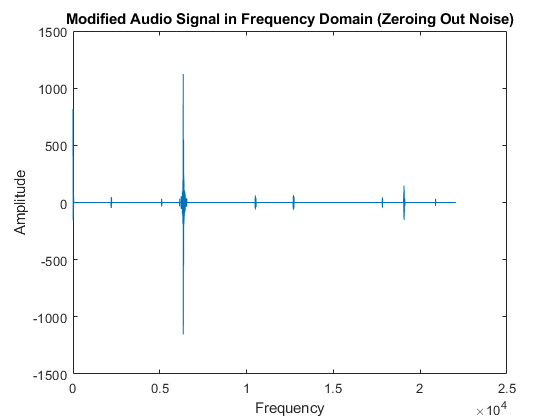

low_amplitude_filtered_spectrum = spectrum;

noise_level = 30;

% low_amplitude_filtered_spectrum(1:10) = 0;
for i = 1:length(low_amplitude_filtered_spectrum)
  if abs(low_amplitude_filtered_spectrum(i)) < noise_level
    low_amplitude_filtered_spectrum(i) = 0;
  end
end

figure; plot(frequencies(1:N/2), real(low_amplitude_filtered_spectrum(1:N/2)));
xlabel("Frequency"); ylabel("Amplitude");
title("Modified Audio Signal in Frequency Domain (Zeroing Out Noise)");

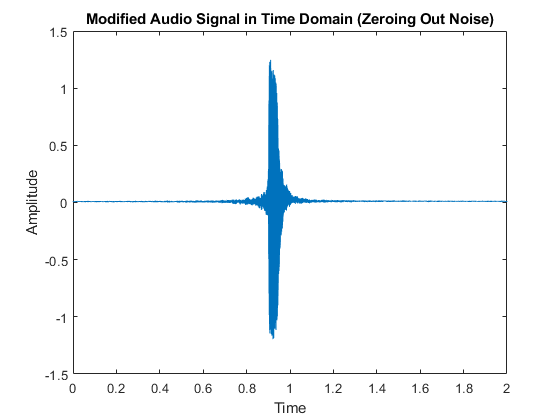

% Apply IFFT

low_amplitude_cleaned_signal = ifft(low_amplitude_filtered_spectrum);
time = linspace(0, length(low_amplitude_cleaned_signal)/sample_rate, length(low_amplitude_cleaned_signal));
figure; plot(time, real(low_amplitude_cleaned_signal));
xlabel("Time"); ylabel("Amplitude");
title("Modified Audio Signal in Time Domain (Zeroing Out Noise)");

audiowrite('export/low_amplitude_cleaned_signal.wav', abs(low_amplitude_cleaned_signal), sample_rate);

## Mean Thresholding

Adaptive thresholding is a technique used in signal processing and image processing to dynamically adjust the threshold for distinguishing between signal and noise based on the local characteristics of the data. Unlike fixed or global thresholding methods, adaptive thresholding considers variations in signal intensity or noise levels across different regions of the signal.

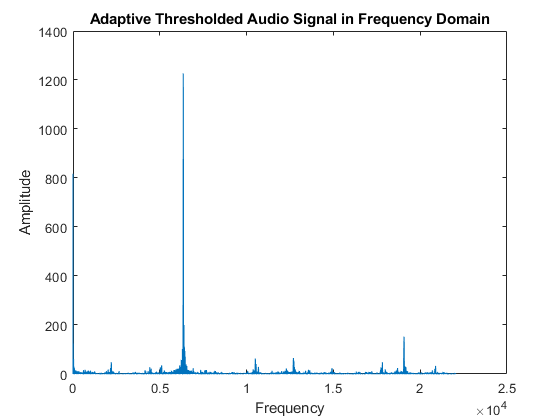

% Adaptive thresholding based on local mean
window_size = 50; % Adjust this value based on your signal characteristics
thresholded_spectrum = zeros(size(spectrum));

for i = 1:length(spectrum)
    start_index = max(1, i - window_size);
    end_index = min(length(spectrum), i + window_size);
    local_mean = mean(abs(spectrum(start_index:end_index)));
    
    % Adaptive thresholding
    if abs(spectrum(i)) > local_mean
        thresholded_spectrum(i) = spectrum(i);
    else
        thresholded_spectrum(i) = 0; % Zero out noise
    end
end

% Plot the thresholded signal in the frequency domain
figure;
plot(frequencies(1:N/2), abs(thresholded_spectrum(1:N/2)));
xlabel("Frequency"); ylabel("Amplitude");
title("Adaptive Thresholded Audio Signal in Frequency Domain");


% Identify the fundamental frequency of the thresholded signal
[maxValue, indexOfMaxValue] = max(thresholded_spectrum);
fundamental_frequency = frequencies(indexOfMaxValue);
disp(['Fundamental Frequency of Adaptive Thresholded Signal: ', num2str(fundamental_frequency), ' Hz']);

Fundamental Frequency of Adaptive Thresholded Signal: 6353.072 Hz


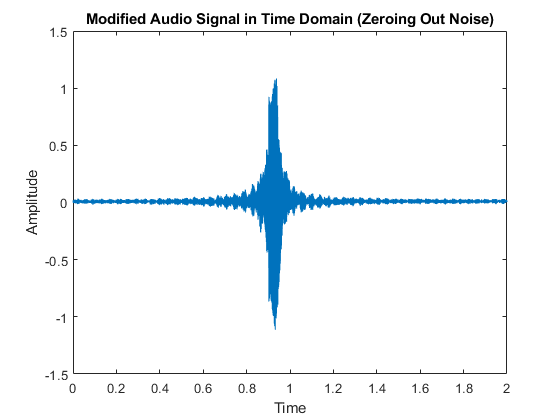

% Apply IFFT
adaptive_thresholded_signal = ifft(thresholded_spectrum);
time = linspace(0, length(adaptive_thresholded_signal)/sample_rate, length(adaptive_thresholded_signal));
figure; plot(time, real(adaptive_thresholded_signal));
xlabel("Time"); ylabel("Amplitude");
title("Modified Audio Signal in Time Domain (Zeroing Out Noise)");

audiowrite('export/adaptive_thresholded_signal.wav', abs(adaptive_thresholded_signal), sample_rate);

## 1. Custom `bandstop` Frequency Filter.

The custom low amplitude frequency filter is designed to target and eliminate specific frequency components characterized by low amplitudes. This tailored approach is effective in addressing noise components that may be perceptually insignificant but contribute to overall signal impurity.

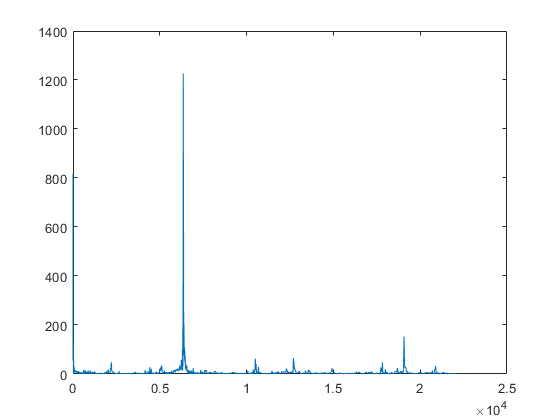

bandstopLower = 5500;
bandstopUpper = 6500;
reducingAmount = 3;

plot(frequencies(1:N/2), abs(spectrum(1:N/2)));

[~, indexOfMaxValue] = max(spectrum);
fundamental_frequency = frequencies(indexOfMaxValue);
disp(['Fundamental Frequency: ', num2str(fundamental_frequency), ' Hz']);

Fundamental Frequency: 6353.072 Hz


filtered_f = spectrum;
% Applying the bandstop filter
for i = 1:N
    if bandstopLower < frequencies(i) &&  frequencies(i) < bandstopUpper
        filtered_f(i) = 0;
    else
        filtered_f(i) = spectrum(i);
    end   
end

% Applying the highpass filter
bandstopUpper = 0.5;
for i = 1:N
    if frequencies(i) < bandstopUpper
        filtered_f(i) = filtered_f(i)*0.05;
    end
end

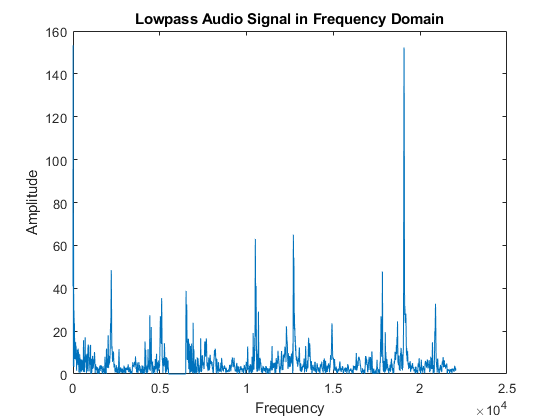

% Plot the filtered signal in the frequency domain
figure; 
plot(frequencies(1:N/2), abs(filtered_f(1:N/2)));
xlabel("Frequency"); ylabel("Amplitude");
title("Lowpass Audio Signal in Frequency Domain");

## Extend the Analysis

These techniques, when applied sequentially or in combination, contribute to a comprehensive noise reduction strategy. Each method addresses specific aspects of noise in the signal spectrum, collectively resulting in a refined and enhanced audio signal. The subsequent re-plotting of the frequency domain graph and exportation of denoised audio files serve as tangible evidence of the successful noise reduction achieved through these methodologies.